%clearing
clear;
clc;
close all;

k = 1; %range from 1-5, this assigns importance of risk, 1 being the highest considering the sharpe ratio

%excel file import
filename = 'fulldata.xlsx';
cdata = readmatrix(filename);
disp(size(cdata));

   120    10



    0.0165
    0.0079
    0.0270
    0.0206
    0.0206
    0.0071
    0.0117
    0.0222
    0.0092
    0.0099

sharpe
    0.2742
    0.0000
    0.1924
    0.0587
    0.1721
    0.2132
    0.0000
    0.0894
    0.0000
    0.0000

    0.3394    0.3444    0.3495    0.3535    0.3509    0.3463    0.3417    0.3371    0.3325    0.3279    0.3233    0.3186    0.3140    0.3094    0.3048    0.3002    0.2956    0.2909    0.2863    0.2817    0.2771    0.2725    0.2679    0.2633    0.2586    0.2540    0.2494    0.2448    0.2402    0.2356    0.2309    0.2263    0.2217    0.1925    0.1543    0.1162    0.0780    0.0398    0.0017         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

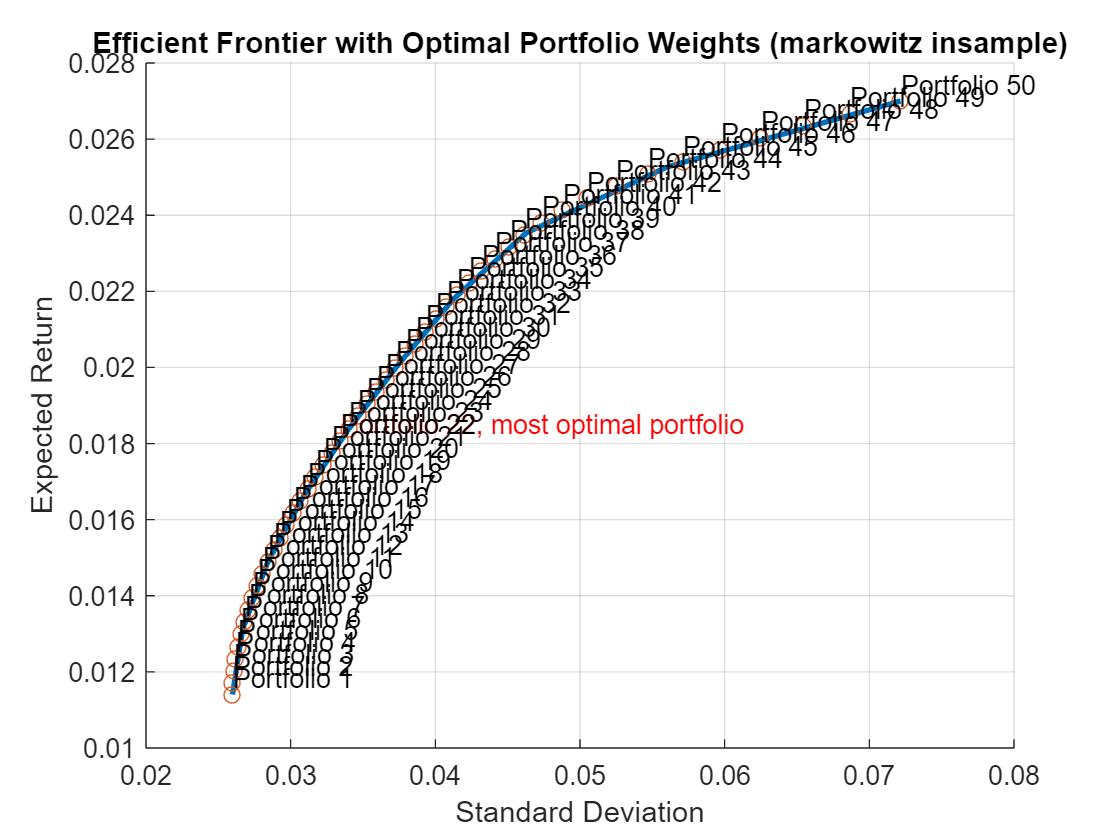


%profile on;
memoryBefore = memory;
[pwgt1, outsamples] = mkmvo(cdata, k);

memoryAfter = memory;
%profile off;
%profile viewer;
disp(memoryAfter.MemUsedMATLAB - memoryBefore.MemUsedMATLAB);

     1851392




%test against outsample returns
%outsampletest(pwgt1, outsamples);